# ECE 486 S23 Project Section 6

### @author Laurent Zheng (20818351)

## A. Initial Tuning of Controller

**1. Computed Torque Controller**

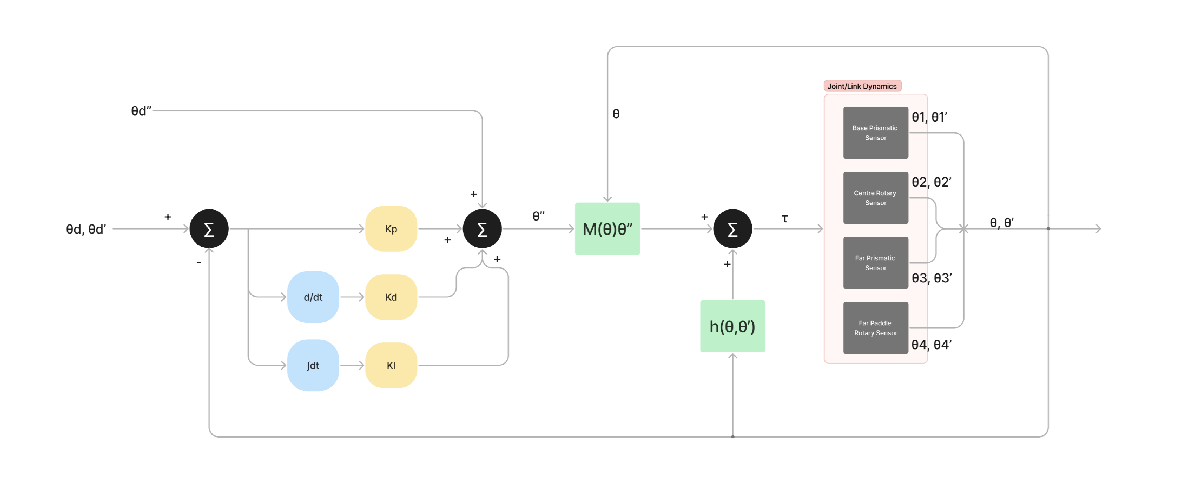

imshow(imread("torque_controller.png"))

**2. Gain Selection:**

The proportional gain $K_p$, determines the system's response to the error between the desired and actual output. A higher $K_p$amplifies the correction, but excessive values can lead to instability. This means we can first set the other gains to 0, and observe the response as we experimentally increase $K_p$ until we see noticable oscillatory terms in the output. 

goal_configs =     0.5000         0    0.4400         0


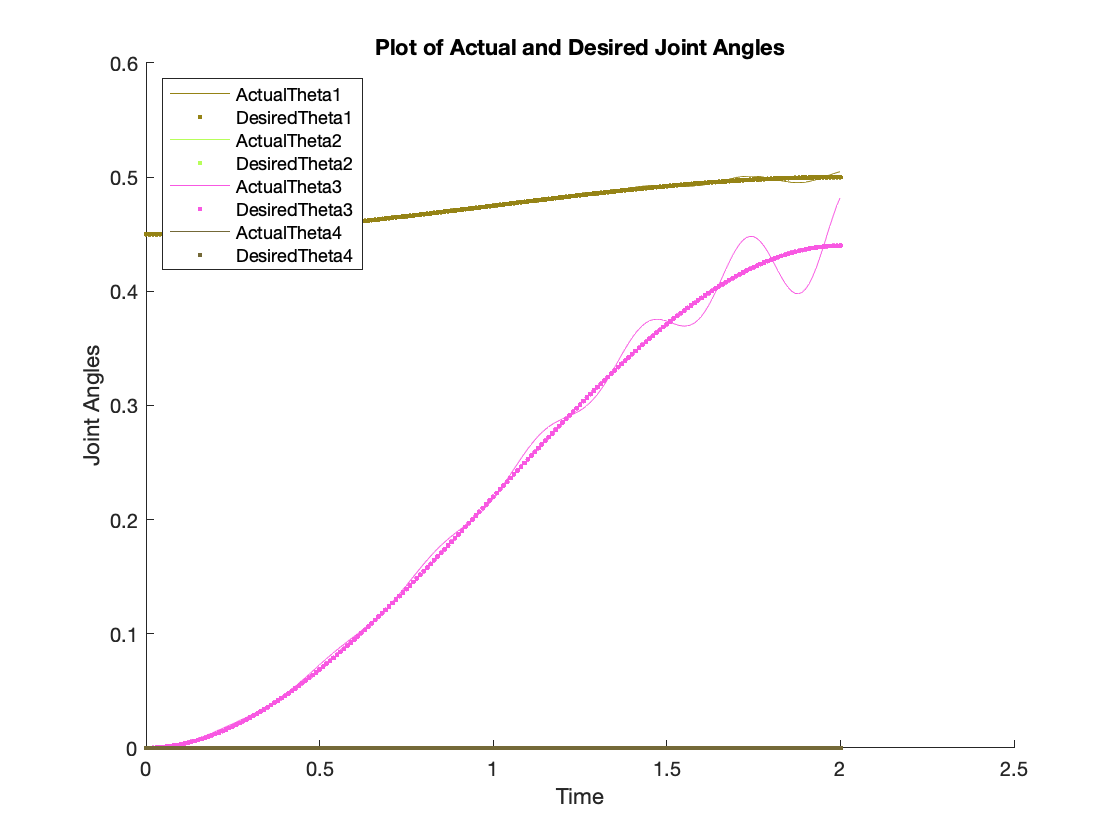

% Generate test points
centre = [0.7, 0, 0.3]';
[px,py,pz] = ndgrid([0.3, 1.1],[-0.8, 0.8],[-0.1, 0.7]);
corners = [px(:), py(:), pz(:)]';

Kp1 = 450;
Kd1 = 0;
Ki1 = 0;


test_points1 = centre;
[T_des1, T_act1] = plot_controlled_output(test_points1, Kp1, Kd1, Ki1, 0);

We can see from above that $K_p$ = 450 shows noiticable oscillation terms in the response going to the centre of the cuboid for T_c between 1 to 3 seconds, which is a fair range of time for the ball to travel to the centre of the cuboid. We will set $K_p$ to half of this value for now at 225.

Next we can increase the integral gain $K_i$, which addresses steady-state errors by integrating the cumulative error over time. Selecting an appropriate $K_i$ can eliminate steady-state errors, but too much integral action can lead to instability and overshoot. We will increase the integral gain until any offset is corrected.

goal_configs =     0.5000         0    0.4400         0


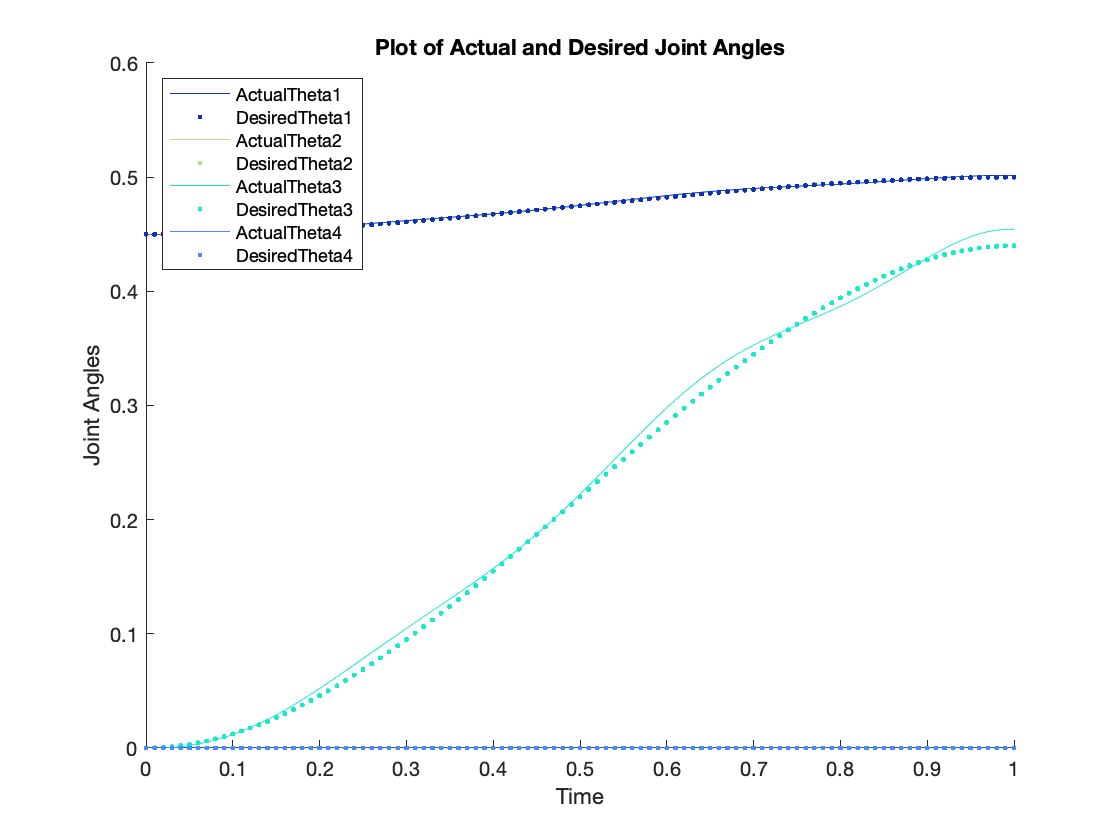

Kp2 = 225;
Kd2 = 0;
Ki2 = 80;


test_points2 = centre;
[T_des2, T_act2] = plot_controlled_output(test_points2, Kp2, Kd2, Ki2, 0)

Here we see that the steady-state error looks diminished at around 80. On the other hand, we see that the system is still quite unstable. We can now adjust the derivative gain until the damping effect smooths-out the instability. The derivative gain $K_d$ also aids in reducing overshoot and improving transient response by considering the rate of error change.

goal_configs =     0.5000         0    0.4400         0


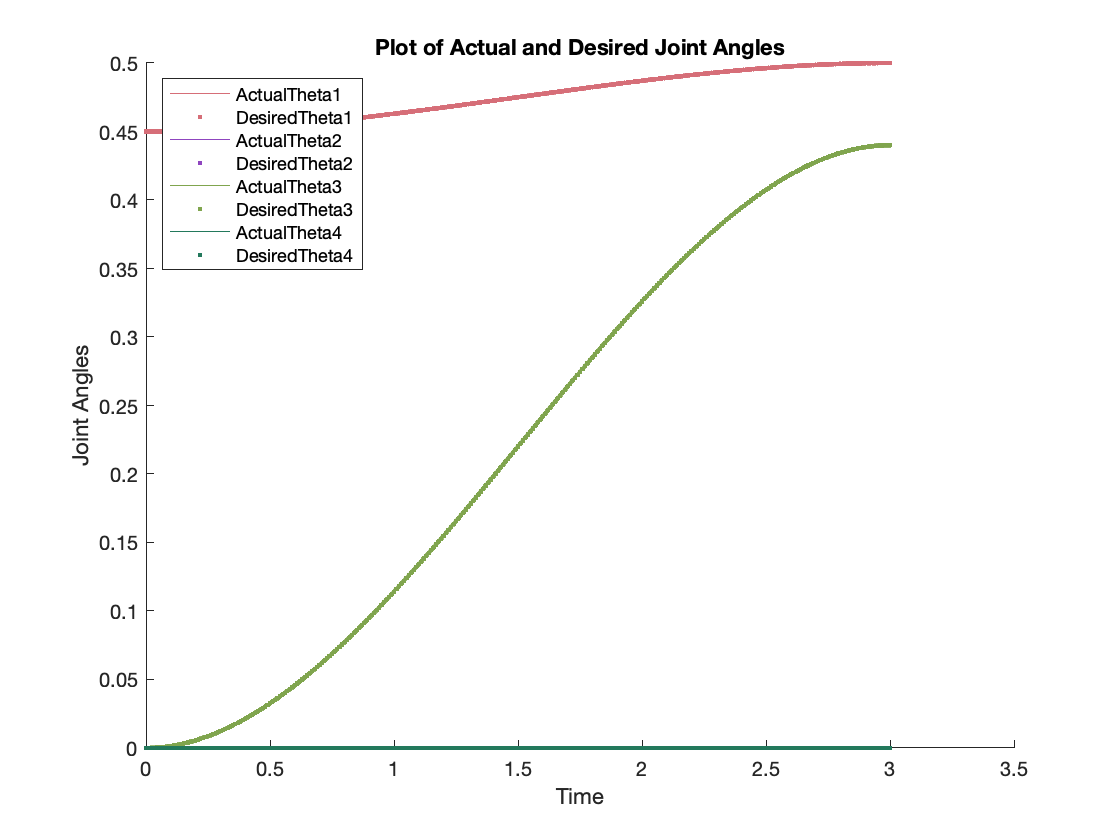

Kp3 = 225;
Kd3 = 50;
Ki3 = 80;

test_points3 = centre;
[T_des3, T_act3] = plot_controlled_output(test_points3, Kp3, Kd3, Ki3, 0);

**3. Testing Various Points in the Cuboid:**

We now have all the gain set for the PID control. The above shows an nearly indentical trajectory from the theoretical. We can also test this with other points in the cuboid.

goal_configs =     0.1000   -0.6119    0.2927    0.6119


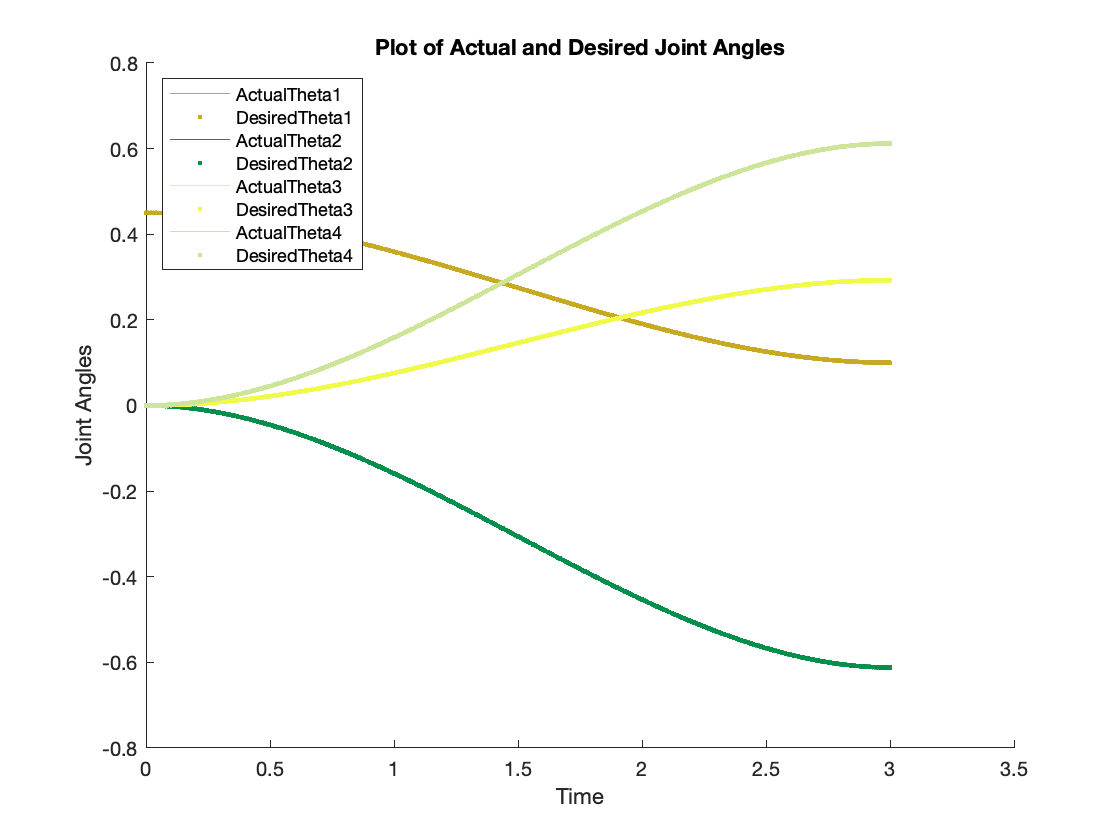

goal_configs =     0.1000   -0.3911    0.9985    0.3911


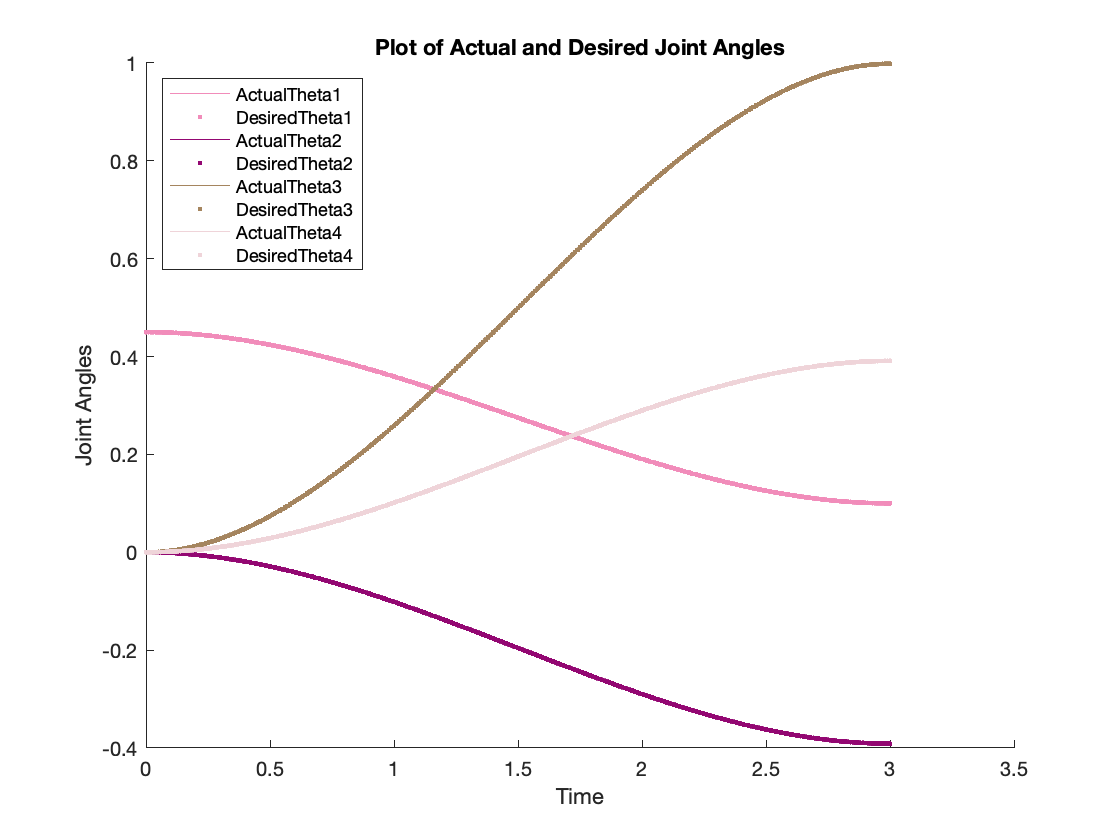

goal_configs =     0.1000    0.6119    0.2927   -0.6119


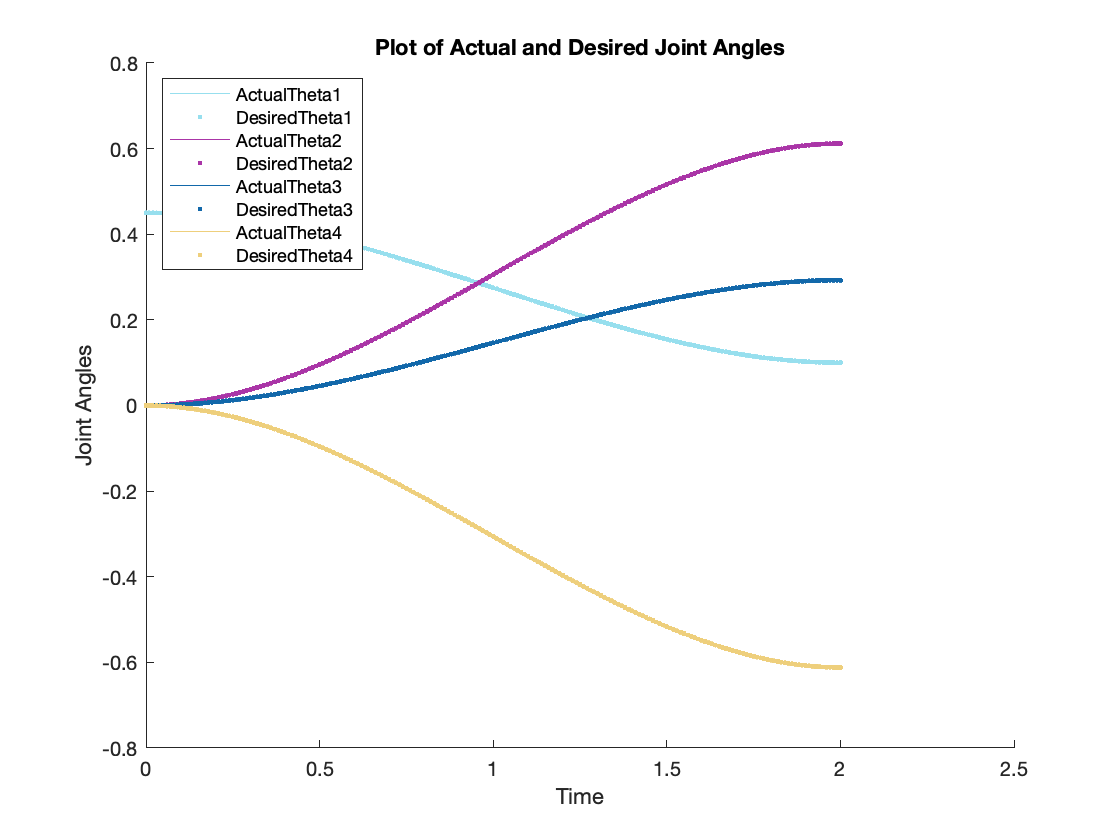

goal_configs =     0.1000    0.3911    0.9985   -0.3911


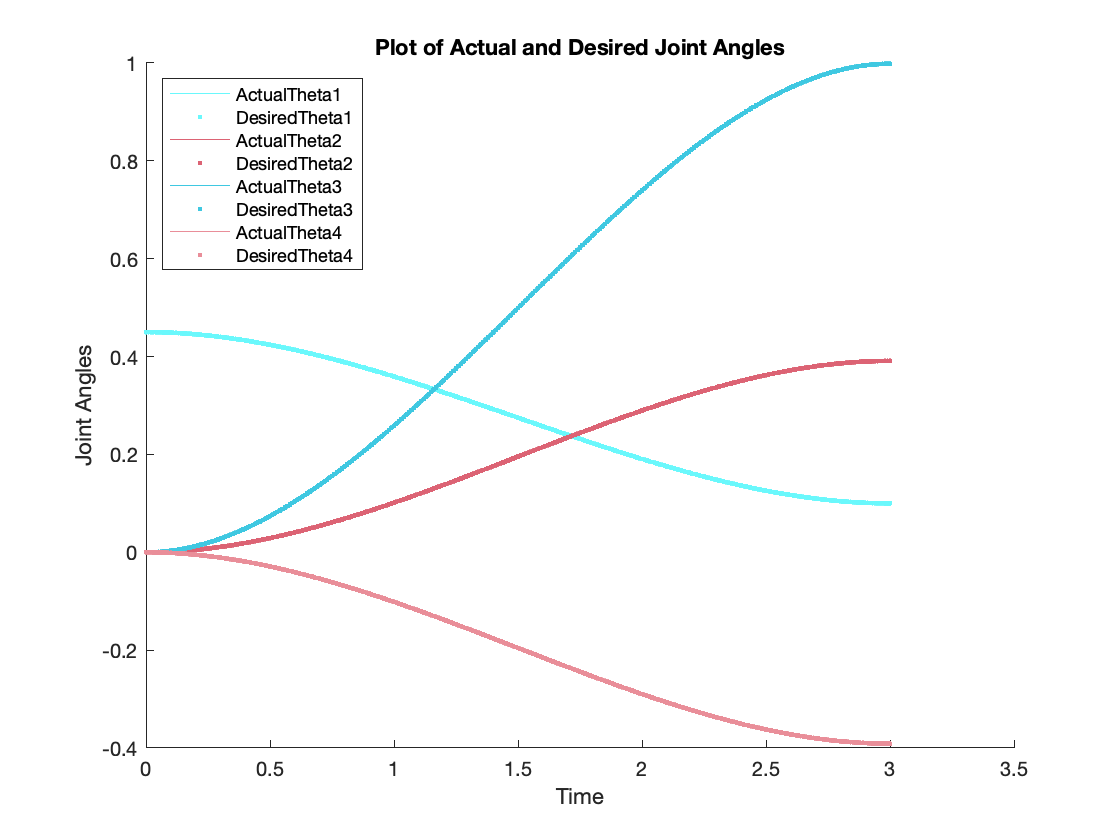

goal_configs =     0.9000   -0.6119    0.2927    0.6119


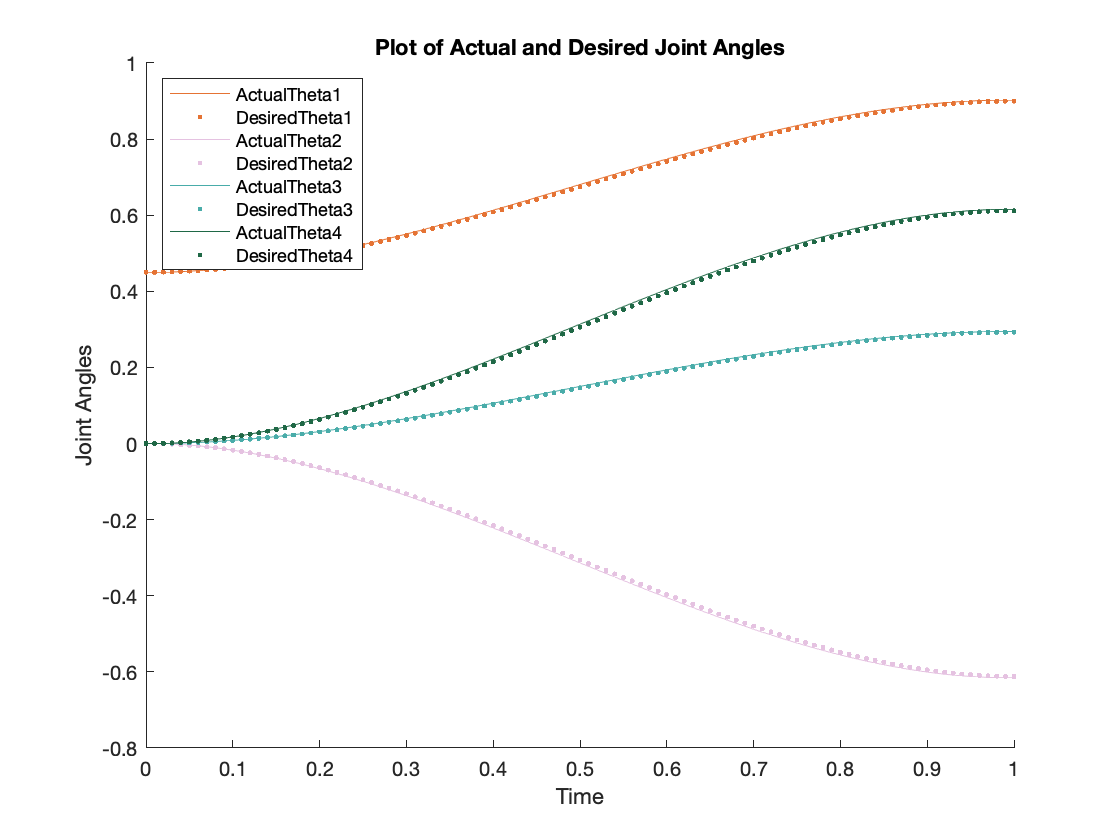

goal_configs =     0.9000   -0.3911    0.9985    0.3911


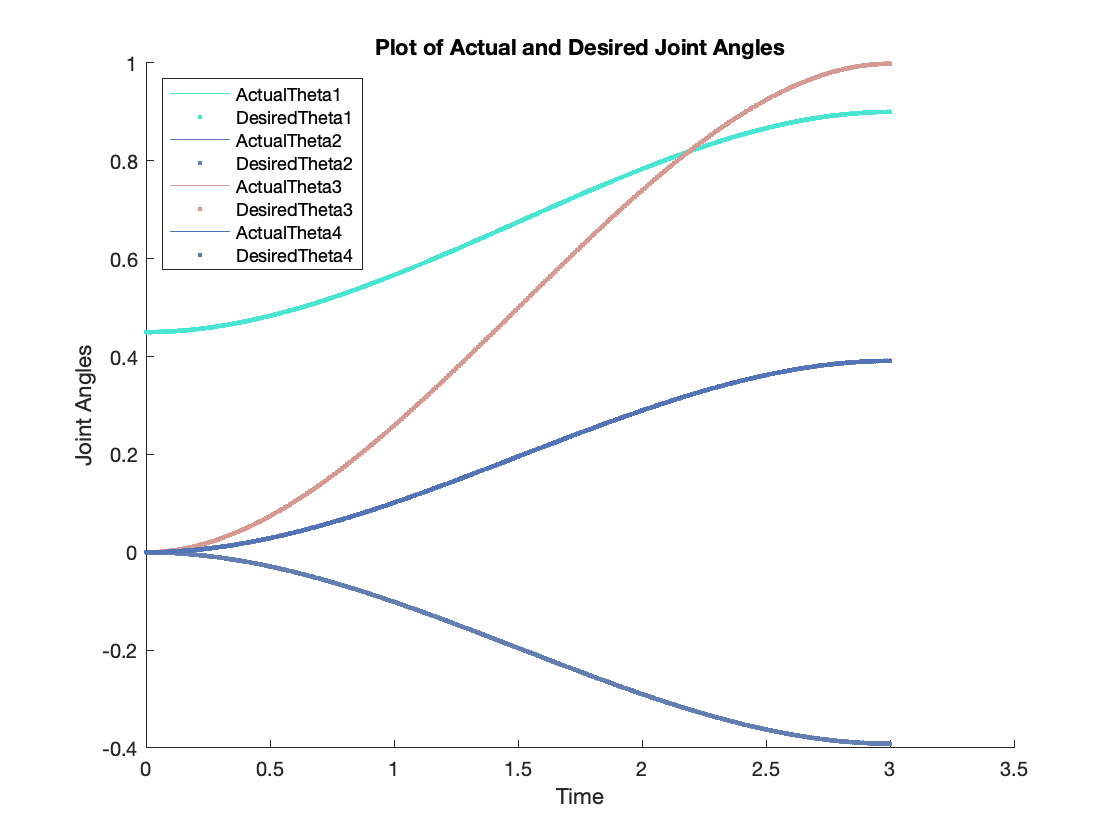

goal_configs =     0.9000    0.6119    0.2927   -0.6119


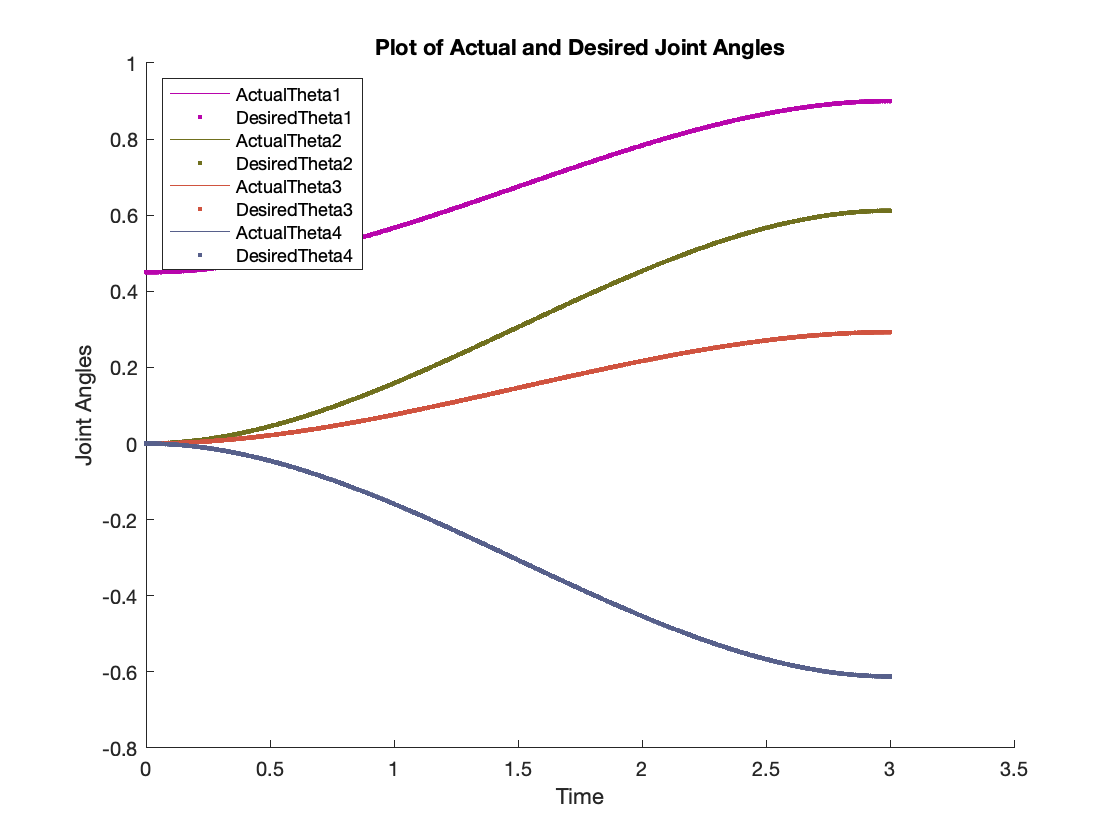

goal_configs =     0.9000    0.3911    0.9985   -0.3911


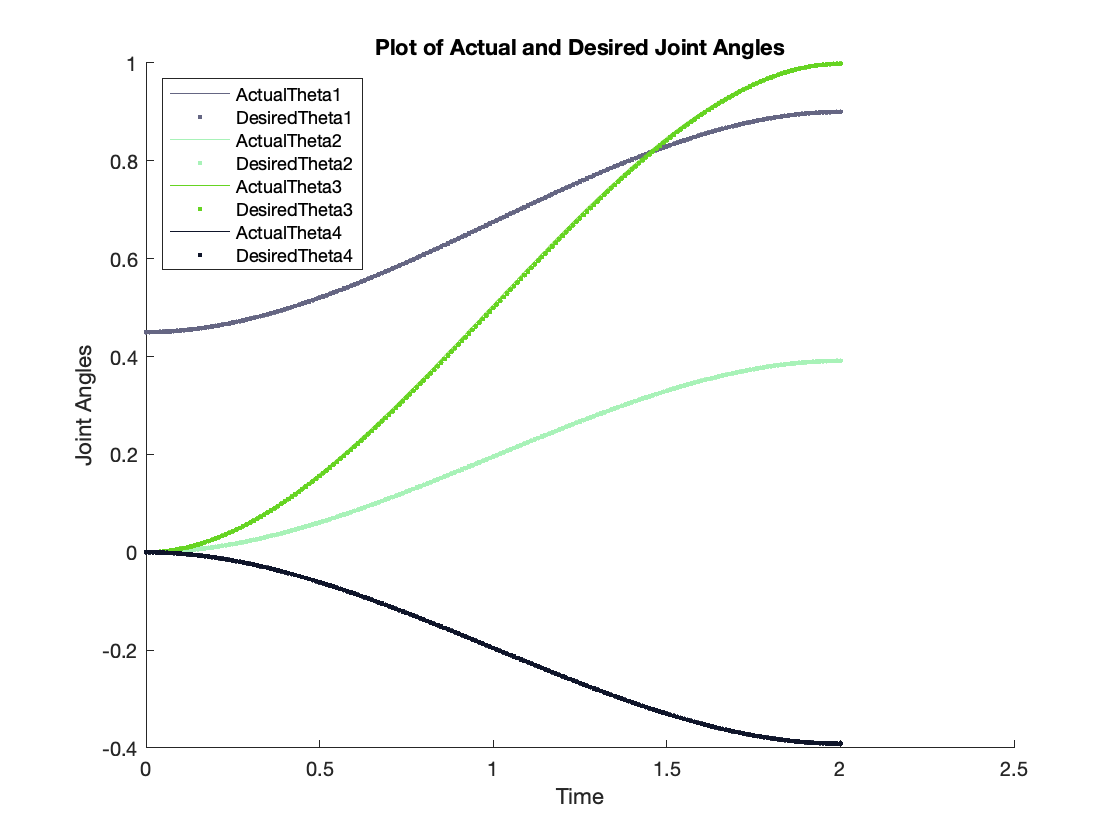

Kp = 225;
Kd = 50;
Ki = 80;

test_points = corners;
[T_des, T_act] = plot_controlled_output(test_points, Kp, Kd, Ki, 0)

Here, we see that the desired and repsonse trajectories for all 8 corner of the cuboid is nearly identical, validating that the chosen gain works quite well.

## B. Function Definitions

We can also test our controller with an imperfect model:

goal_configs =     0.1000   -0.6119    0.2927    0.6119


goal_configs =     0.1000   -0.3911    0.9985    0.3911


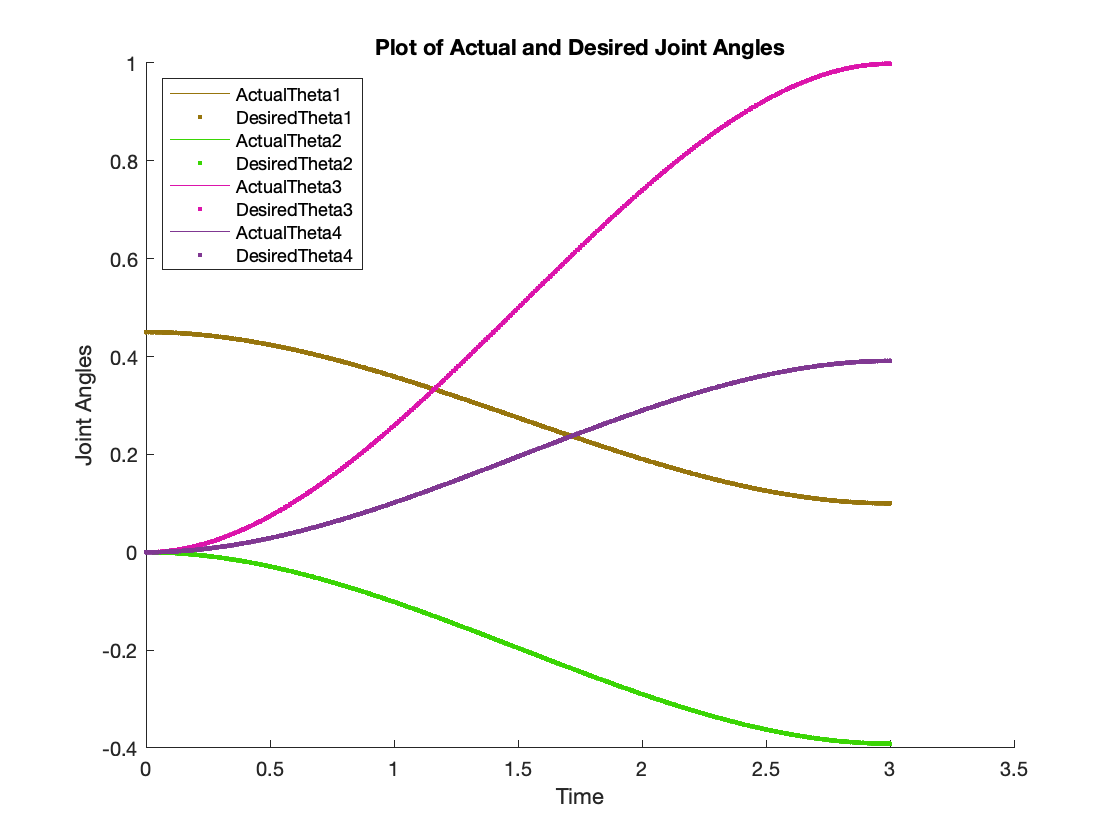

goal_configs =     0.1000    0.6119    0.2927   -0.6119


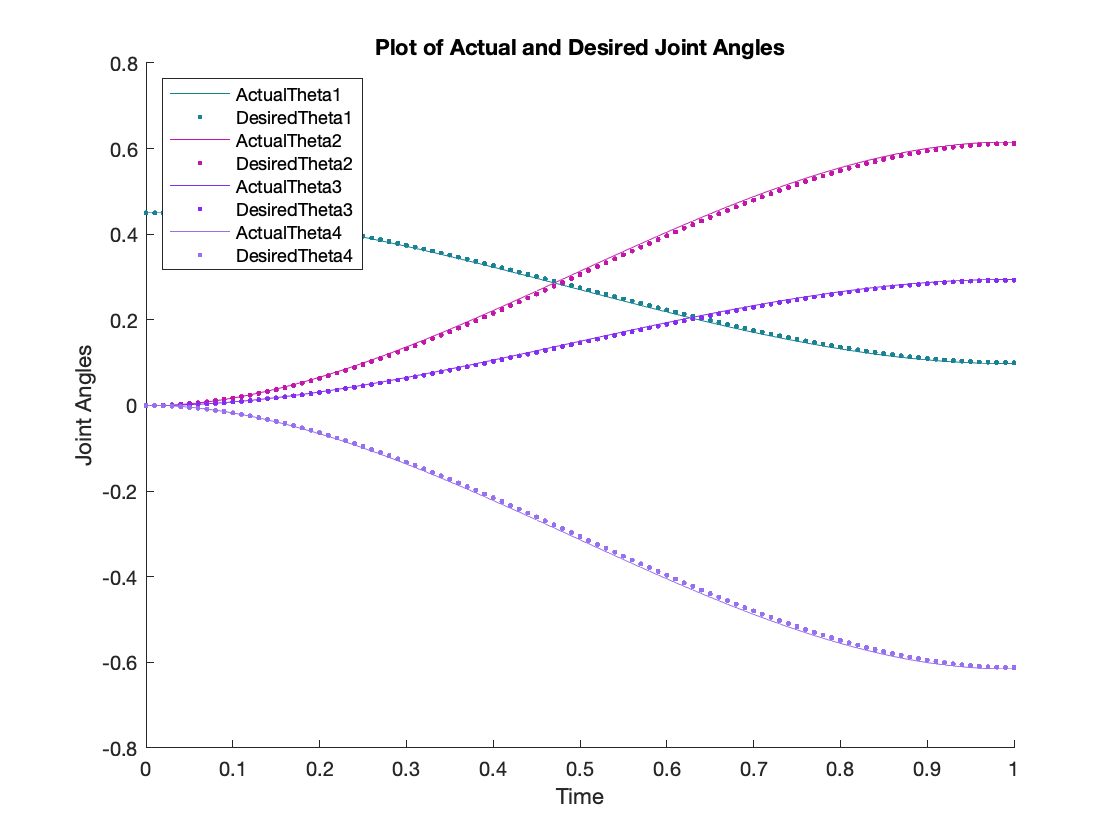

goal_configs =     0.1000    0.3911    0.9985   -0.3911


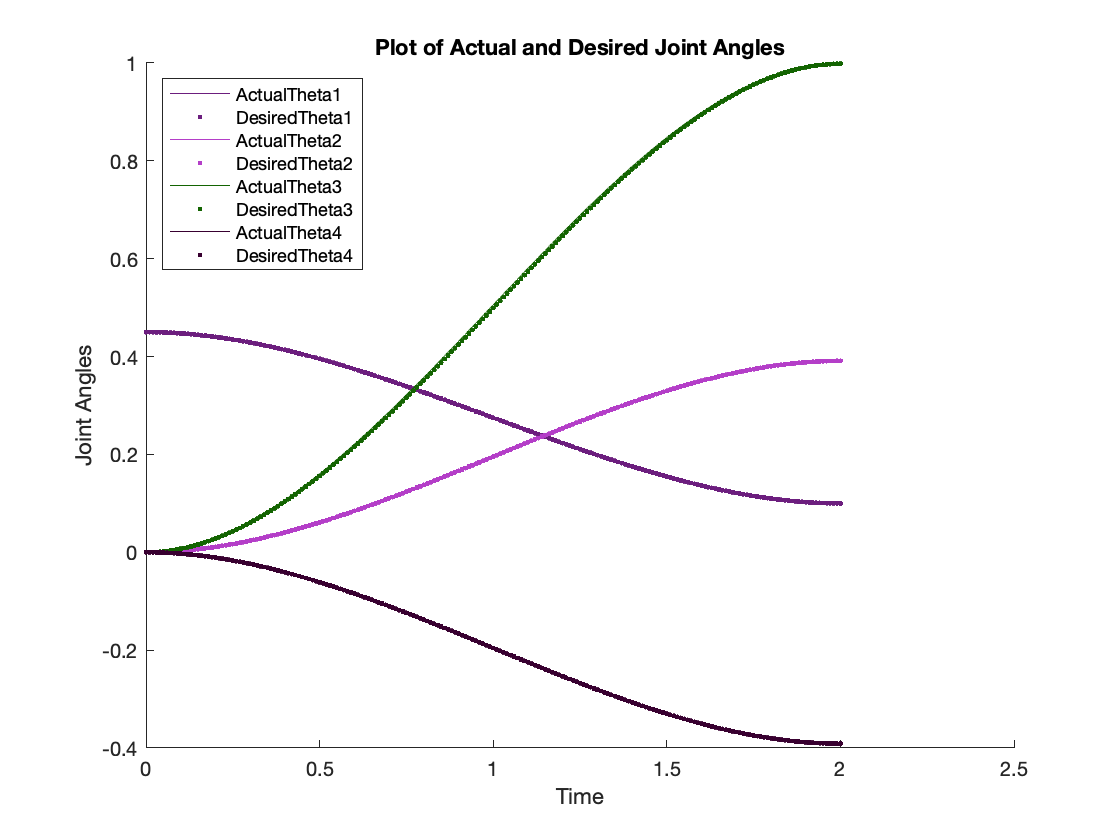

goal_configs =     0.9000   -0.6119    0.2927    0.6119


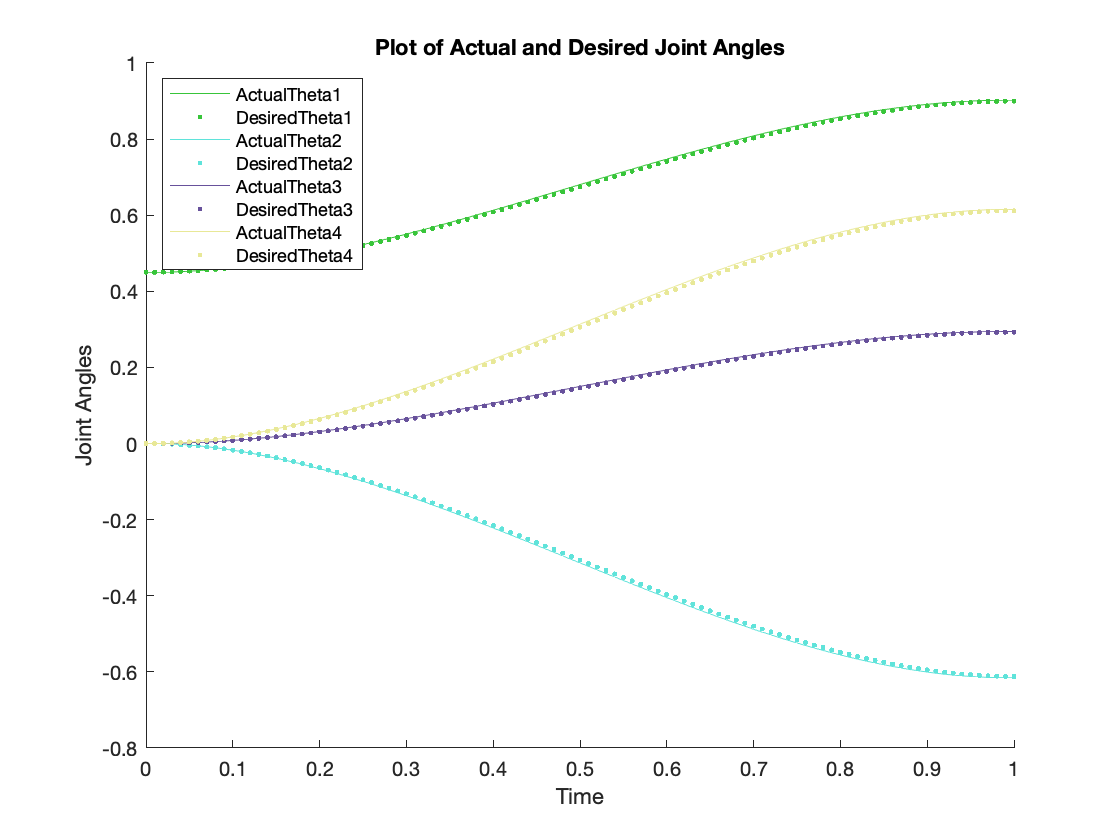

goal_configs =     0.9000   -0.3911    0.9985    0.3911


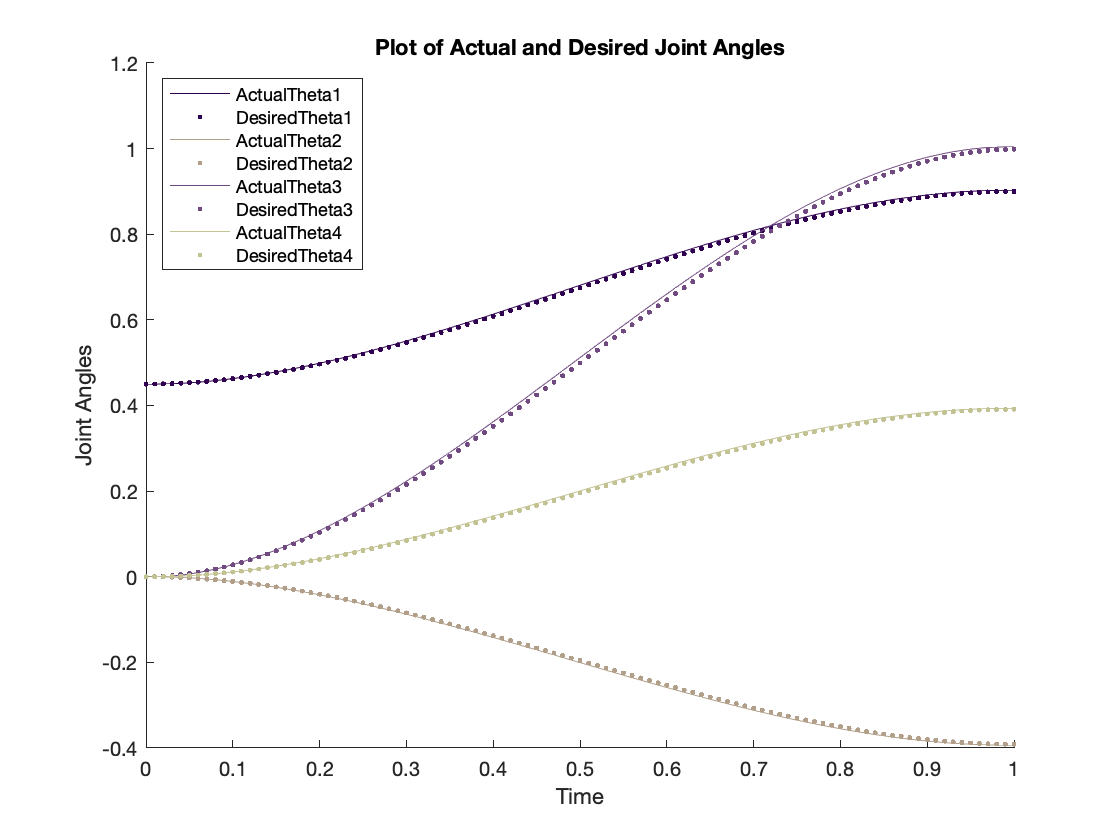

goal_configs =     0.9000    0.6119    0.2927   -0.6119


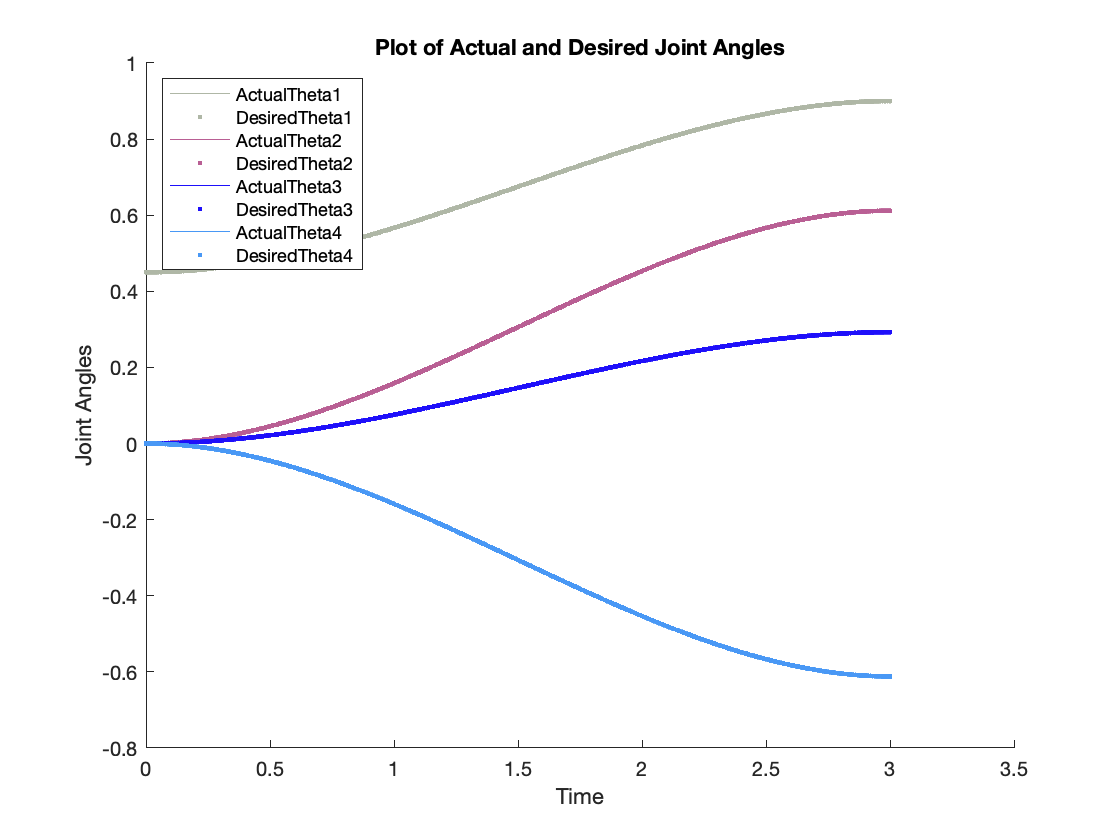

goal_configs =     0.9000    0.3911    0.9985   -0.3911


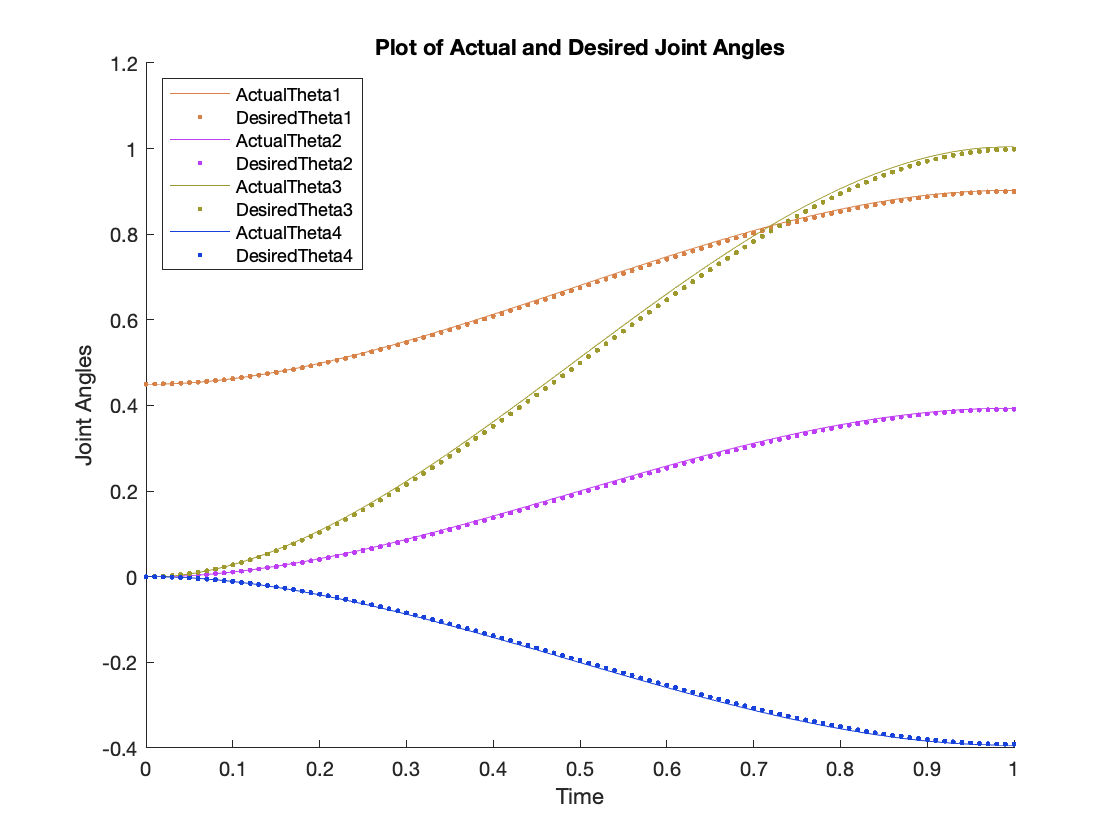

[T_des, T_act] = plot_controlled_output(test_points, Kp, Kd, Ki, 1); % setting the last input as 1 gives imperfect mass matrix.

From the above plots, we can see that our controller can very resonably follow the imperfect model. 

**2. Discussions:**

In a real-world scenario, this simulation would help predict how the robotic system will respond to the controller inputs and external forces. This is valuable for verifying the controller's effectiveness and safety before applying it to the physical robot. Before implementing the controller on an actual robot, it is important to thoroughly validate and test the controller's performance in simulation. The provided code includes checks for imperfect model conditions, which can help assess the controller's robustness to uncertainties. Once the controller is well-tuned and validated in simulation, it can be integrated with the physical robot hardware. This integration process involves adapting the code to communicate with the robot's sensors (e.g., encoders) and actuators (e.g., motors), as well as handling any real-world constraints or limitations.

Robustness to imperfect models is vital for real-world robotic applications due to uncertainties, model drift, safety concerns, limited identifiability, variations, and adaptability challenges. This is especially true for different manufactuors and materials for the design that would change the mass matrices from the perfect model. A robust controller can handle unpredictable dynamics, changing conditions, and unknown parameters, ensuring reliable performance, preventing catastrophic failures, and reducing development and maintenance costs. By accommodating real-world complexities, a robust controller enhances the adaptability and resilience of robotic systems, enabling them to function effectively and safely in diverse and challenging environments.

function [T_des, T_act] = plot_controlled_output(test_points, Kp, Kd, Ki, is_imperfect)

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
% g - acceleration due to gravity (relative to the fixed frame)
R_sh = [0 1 0; 0 0 1; 1 0 0]';
p_sh = [0.25 0 0.25]';
T_sh = RpToTrans(R_sh, p_sh);
g = [0; 0; -9.8];

% Robot Design (copied from Section 3: Design or your revised design)
% Define joint_types, joint_limits, B_list, S_list, and M
joint_types = ['P','R','P','R'];
joint_limits = [[0;1],[-pi;pi],[0;1],[-pi/2;pi/2]];
S_list = [[0;0;0;0;0;1],[0;0;1;0;0.9;0]  ,[0;0;0;1;0;0],[0;0;1;0;-0.2;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
B_list = [[0;0;0;0;1;0],[0;1;0;1.15;0;0],[0;0;0;0;0;1],[0;1;0;0.05;0;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
M = [0 0 1 0.25; 1 0 0 0; 0 1 0 -0.2; 0 0 0 1]; % must be in SE(3)
speed_limits(joint_types == 'P') = 0.5;
speed_limits(joint_types == 'R') = 2;
n_joints = length(joint_types);

% Robot Dynamic Parameters
% Define M_list and G_list
% Robot Dynamic Parameters
% Define M_list and G_list
R01 = eye(3);
p01 = [0 0 0.15]';
M01 = RpToTrans(R01, p01);

R12 = [0 0 -1;
       0 1 0;
       1 0 0];
p12 = [0.275 0 0.15]';
M12 = RpToTrans(R12, p12);

R23 = eye(3);
p23 = [0 0 0.55]';
M23 = RpToTrans(R23, p23);

R34 = eye(3);
p34 = [0 0 0.295]';
M34 = RpToTrans(R34, p34);

M_list = cat(3, M01, M12, M23, M34, T_sh); % concatenates the matrices into a list of n+1 matrices



m1 = 3;
r1 = 1;
h1 = 0.3;
I1 = [m1 * (3*r1.^2 + h1.^2)/12, 0, 0;
      0, m1 * (3*r1.^2 + h1.^2)/12, 0;
      0, 0, m1 * r1.^2 / 2];
G1 = [I1, zeros(3);
     zeros(3), m1 * eye(3)];
% must be a 6x6 matrix with a 3x3 rotational inertia in the top left corner and mass*eye(3) in the bottom right corner



m2 = 5.5;
r2 = 1;
h2 = 0.55;
I2 = [m2 * (3*r2.^2 + h2.^2)/12, 0, 0;
      0, m2 * (3*r2.^2 + h2.^2)/12, 0;
      0, 0, m2 * r2.^2 / 2];
R02 = R01 * R12;

G2 = [R02.' * I2 * R02, zeros(3);
     zeros(3), m2 * eye(3)];


m3 = 5.5;
r3 = 1;
h3 = 0.55;
I3 = [m3 * (3*r3.^2 + h3.^2)/12, 0, 0;
      0, m3 * (3*r3.^2 + h3.^2)/12, 0;
      0, 0, m3 * r3.^2 / 2];
R03 = R02 * R23;

G3 = [R03.' * I3 * R03, zeros(3);
     zeros(3), m3 * eye(3)];

m4 = 0.4;
r4 = 1;
h4 = 0.04;
I4 = [m4 * (3*r4.^2 + h4.^2)/12, 0, 0;
      0, m4 * (3*r4.^2 + h4.^2)/12, 0;
      0, 0, m4 * r4.^2 / 2];
R04 = R03 * R34;

G4 = [R04.' * I4 * R04, zeros(3);
     zeros(3), m4 * eye(3)];


G_list = cat(3, G1, G2, G3, G4); % concatenates the matrices into a list of n matrices

% Set up the required variables
freq = 100; % use a 100 Hz sampling rate
dt = 1/freq; % time step is the inverse of the sampling frequency
intRes = 1; % integral resolution for the forward dynamics

for i=1:size(test_points,2)
    % Use the trajectory generation function to get a trajectory the given point
    p_sb = test_points(:,i);
    tc = randi([1, 3]);
    thetades = generate_trajectory(p_sb,tc,freq);
    
    % Generate matrices of tip forces, velocities and accelerations
    n_samples = size(thetades,1);
    dthetades = [zeros(1,n_joints);diff(thetades)*freq]; % joint velocities
    ddthetades = [zeros(1,n_joints);diff(dthetades)*freq]; % joint accelerations
    Ftipdes = zeros(n_samples, 6); % should always have 0 force on tip

    % perfect model
    gtilde = g;
    Gtildelist = G_list;
    Mtildelist = M_list;  

    if is_imperfect
        gtilde = gtilde*(1+(rand()-.5)/50);
        for j = 1:size(G_list,3)
            Gtildelist(1:3,1:3,j) = Gtildelist(1:3,1:3,j)*(1+(rand()-.5)/50);
            Gtildelist(4:6,4:6,j) = eye(3)*Gtildelist(6,6,j)*(1+(rand()-.5)/50);
        end
        for k = 1:size(M_list,3)
            Mtildelist(1:3,4,k) = Mtildelist(1:3,4,k).*(1+(rand(3,1)-.5)/50);
        end
    end
    
    % generate the list of actual joint angles
    [~, thetamat] ...
         = SimulateControl(thetades(1,:)', dthetades(1,:)', g, Ftipdes, M_list, ...
                           G_list, S_list, thetades, dthetades, ...
                           ddthetades, gtilde, Mtildelist, Gtildelist, ...
                           Kp, Ki, Kd, dt, intRes);
                       
    % Get the end effector pose at contact time
    T_des = FKinSpace(M, S_list, thetades(tc*freq+1,:)'); % Get the desired pose at the time of contact (based on traj gen)
    T_act = FKinSpace(M, S_list, thetamat(tc*freq+1,:)'); % Get the actual pose at the time of contact (based on the control loop)

end

end

function [T_sc, solution_list] = inverse_kinematics(var)
if size(var)==[4 4] & TestIfSE3(var)
    % The input variable is in SE(3), so set T_sc to the input
    T_sc = var;
else
    % The input variable is not in SE(3), so set p_sb to the input
    p_sb = reshape(var,[3,1]);

    % Generate a desired contact pose T_sc given the ball position p_sb
    % Note: Copy this section from the IK problem in Section 4: Validation
    R_sh = [0 0 1; 1 0 0; 0 1 0];
    p_sh = [0.25; 0; 0.25];
    T_sh = RpToTrans(R_sh, p_sh);
    
    contact_angle = 0;
    p_hb = T_sh \ [p_sb; 1];
    p_hb = p_hb(1:end-1);
    
    R_hc = [cos(contact_angle) 0 sin(contact_angle); 0 1 0; -sin(contact_angle) 0 cos(contact_angle)];
    p_hc = p_hb - (R_hc * [0; 0; 0.01]);
    T_hc = RpToTrans(R_hc, p_hc);
    
    T_sc = T_sh * T_hc;
end

% Find all valid solutions of the IK problem for your robot to place the paddle in pose T_sc
% Note: Copy this section from the IK problem in Section 4: Validation
% Note: If T_sc is provided, it may be the home pose outside the cuboid
if size(var)==[4 4] & TestIfSE3(var)
    [~,p_sb] = TransToRp(var);
end

contact_angle = 0;
    
% calculation follows derivation above (Here we just merged delta into alpha)
alpha = p_sb(1) + 0.9 - cos(contact_angle)*0.06;
beta = p_sb(2) + sin(contact_angle)*0.06;
theta1 = 0.2 + p_sb(3);
theta2 = atan2(beta, alpha);
theta3 = sqrt(beta.^2 + alpha.^2) - 1.1;
theta4 = contact_angle - theta2;
sol = [theta1, theta2, theta3, theta4];
solution_list = [];

% check if ball is in cuboid before assigning solution: NOTE only one
% unique solution in our case.
if p_sb(1) >= 0.3 && p_sb(1) <= 1.1 && ...
   p_sb(2) >= -0.8 && p_sb(2) <= 0.8 && ...
   p_sb(3) >= -0.1 && p_sb(3) <= 0.7
    solution_list = [sol];
end

if p_sb == [0.25 0 0.25]'
    solution_list = [0.45,0,0,0];
end

end

% Inputs
% p_sb - The position of the ball at time tc (in the fixed frame)
% t_c - The time at which the ball will be at p_sb
% freq - The sampling frequency (in Hz) used to generate your trajectory
% Outputs
% joint_traj - A matrix defining a joint trajectory were each row is a set of joint positions. Empty matrix if no solution found.
function joint_traj = generate_trajectory(p_sb, t_c, freq)
    % Find all valid configurations which contact the ball at p_sb
    [~, goal_configs] = inverse_kinematics(p_sb)
    if isempty(goal_configs)
        joint_traj = [];
        return;
    end
    
    % Find all valid home configurations
    T_sh = RpToTrans([0 1 0; 0 0 1; 1 0 0]', [0.25 0 0.25]');
    [~, home_configs] = inverse_kinematics(T_sh);

% Find a valid trajectory for your robot to follow to end up with the paddle at rest in pose T_sc at or before t_c

% NOTE: Uncomment the following to use trapeziodal trajectory instead

% ts = 1/freq;
% T = t_c;
% v = 1.5/T;
% 
% acc = (v^2)/(v*T - 1);
% t1 = 0:ts:(v/acc);
% t2 = (v/acc+ts):ts:(T-v/acc-ts);
% t3 = (T-v/acc):ts:T;
% 
% time_f1 = (1/2) * acc * t1.^2;
% time_f2 = v * t2 - (v.^2) / (2*acc);
% time_f3 = ( 2*acc*v*T - 2*(v.^2) - (acc^2)* ((t3-T).^2) ) / (2*acc);
% time_f = [time_f1 time_f2 time_f3]';
% 
% while (t_c*freq) >= size(time_f)
%     time_f = [time_f; 1];
% end

% 3rd order time saling trajectory
ts = 1/freq;
T = t_c;
t = 0:ts:T;
time_f = (3.*t.^2/T.^2 - 2.*t.^3/T.^3).';

joint_traj = home_configs + (time_f)*(goal_configs - home_configs);


end
